# Isolated Off-Board Charger for Electric Vehicles

## **Before you get started**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternatively, select **Hide Code **using the icon   at the top right of the Live Editor pane.

Some interactions require basic MATLAB familiarity. If you need a refresher, MATLAB Onramp is a free, two-hour tutorial that covers the essentials.[](https://www.mathworks.com/learn/tutorials/matlab-onramp.html)

Work through the sections in order. Some sections use variables created earlier, so running sections out of sequence may produce errors.

## 1. Introduction

An **off-board charger** is a type of battery charging system designed to recharge electric vehicles (EVs) or other battery-powered systems. Unlike on-board chargers, which are integrated into the vehicle, off-board chargers are standalone devices. These chargers are commonly found at charging stations or in facilities where high-powered and rapid charging is needed.

Off-board chargers are particularly suited for scenarios requiring high charging power or where space constraints in the vehicle make it impractical to include a high-capacity charging system. They can deliver direct current (DC) power directly to the battery, bypassing the vehicle’s onboard charger. This approach enables faster charging and greater efficiency compared to alternating current (AC) charging, which requires conversion within the vehicle.

In an isolated off-board charger, a transformer provides galvanic isolation between the grid-side converter and the battery-side converter. In this model, LLC resonant converters are used as part of the DC-AC-AC-DC conversion path.

By the end of this activity, you should be able to explain why galvanic isolation is used, how the transformer changes the converter structure, and how the charging and inverter controls coordinate during operation.

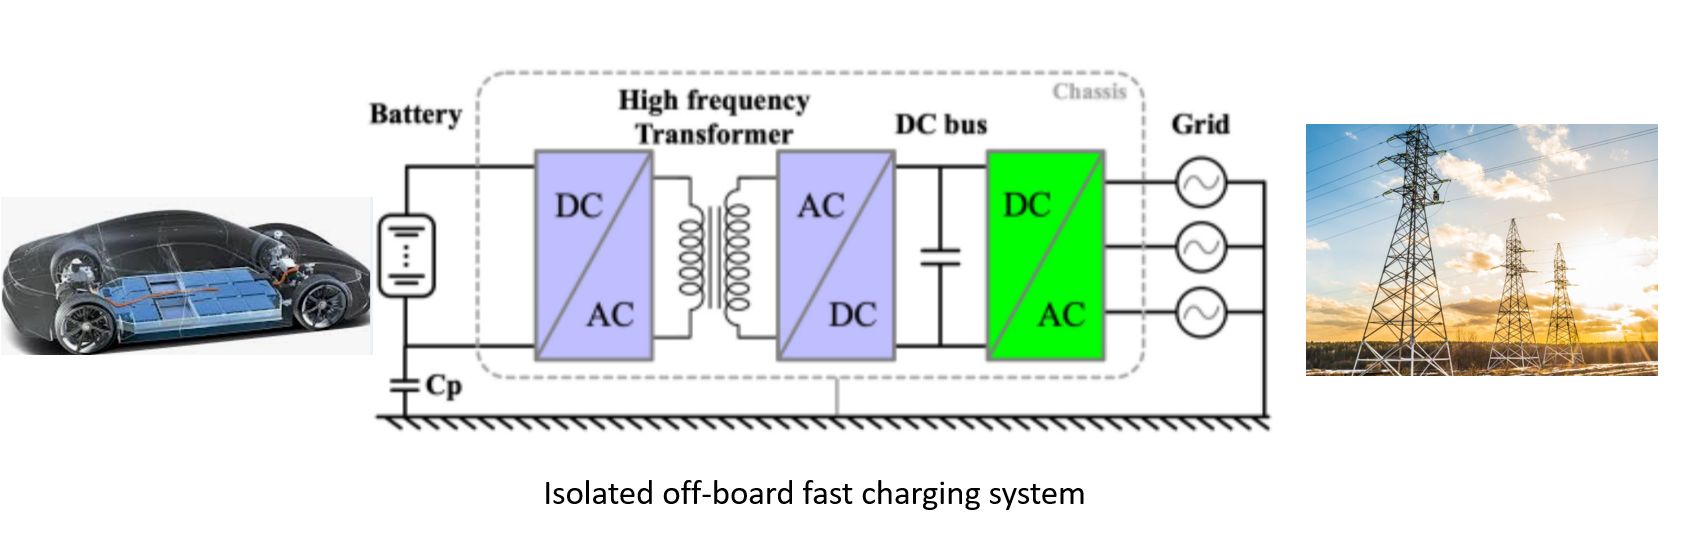

## 2. Circuit

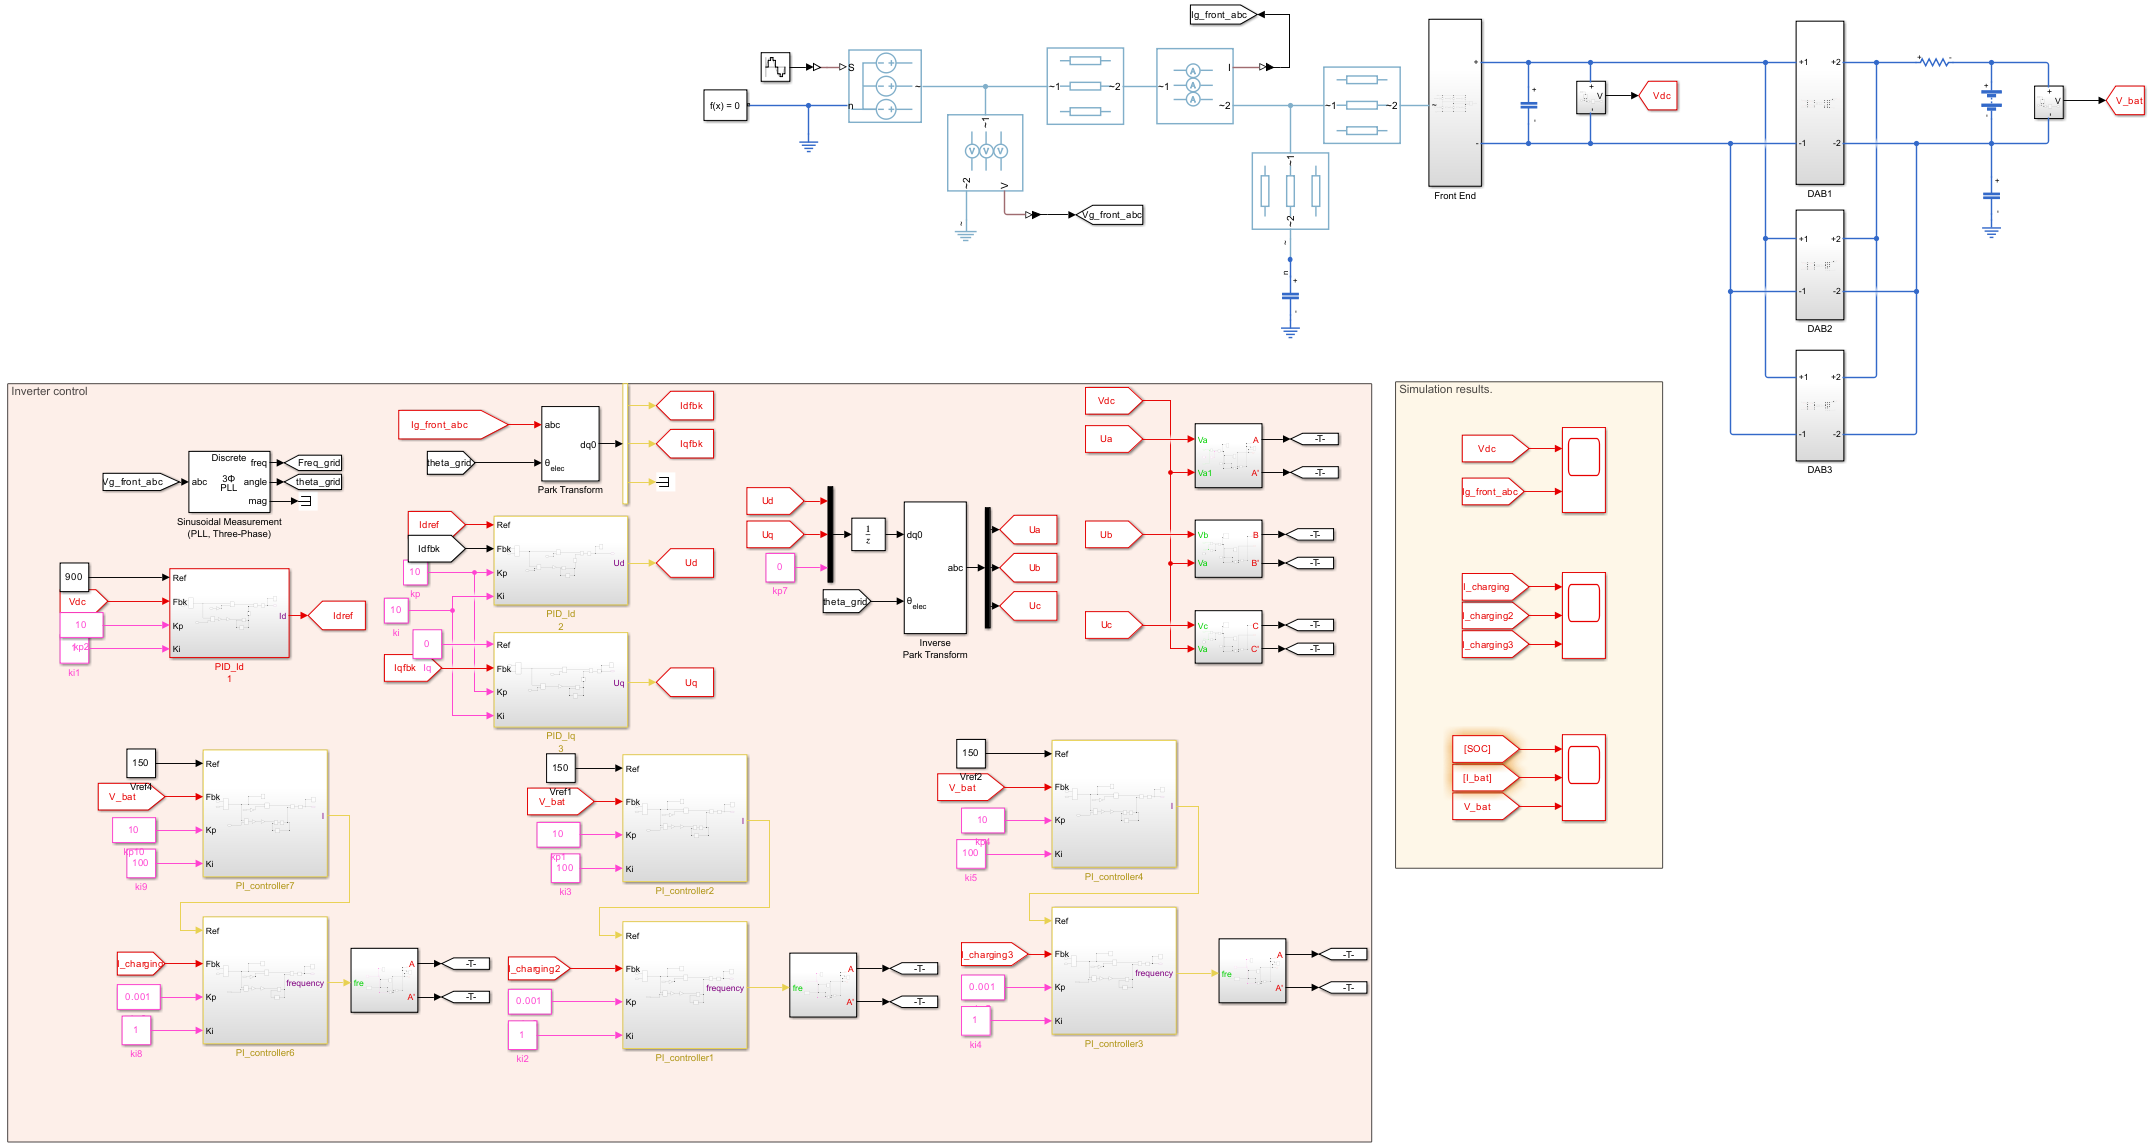

Open the model and identify the stages that provide grid connection, isolation, and battery charging.

 
open_system("Models/Isooffboard_SSC.slx")
if ~exist('V_ref_isolated','var')
    V_ref_isolated = 900;  
end

Use the menu below to focus on each part of the model and connect it to the overall charging path.

switchRectifier("No Selection");

### 2.1 Connect to the Grid

For this simulation, the inverter output must match the grid frequency and phase angle. A phase-locked loop (PLL) estimates the grid phase and frequency. You do not need to analyze the PLL internals here; focus on how synchronization supports grid connection.

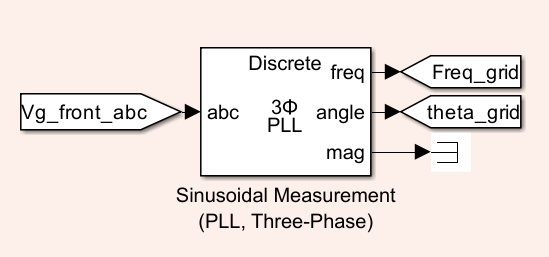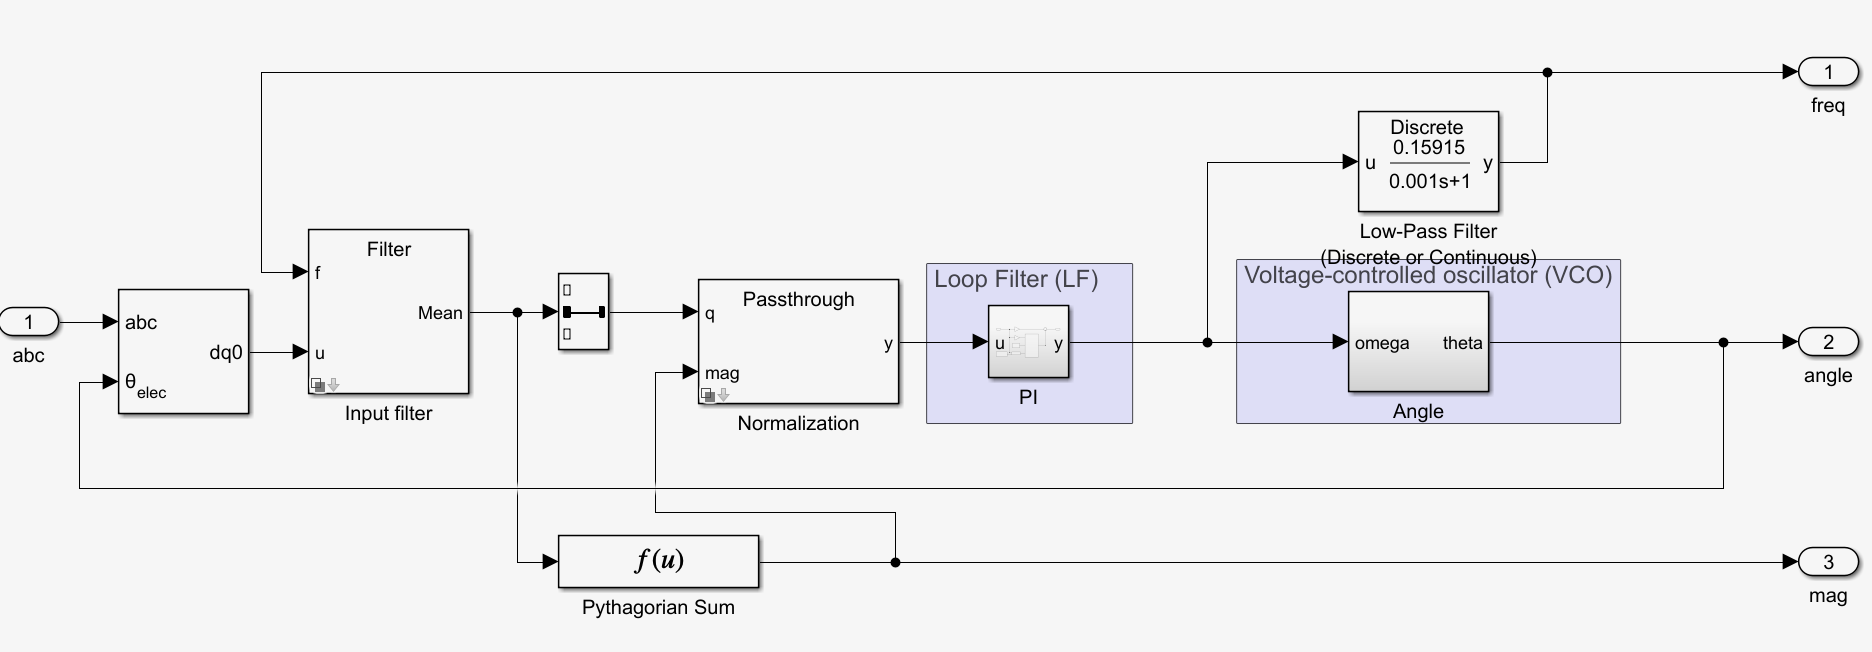

## 3. Control Algorithm

The control algorithm has two major parts: charging current/voltage control, and inverter and DC-bus control.

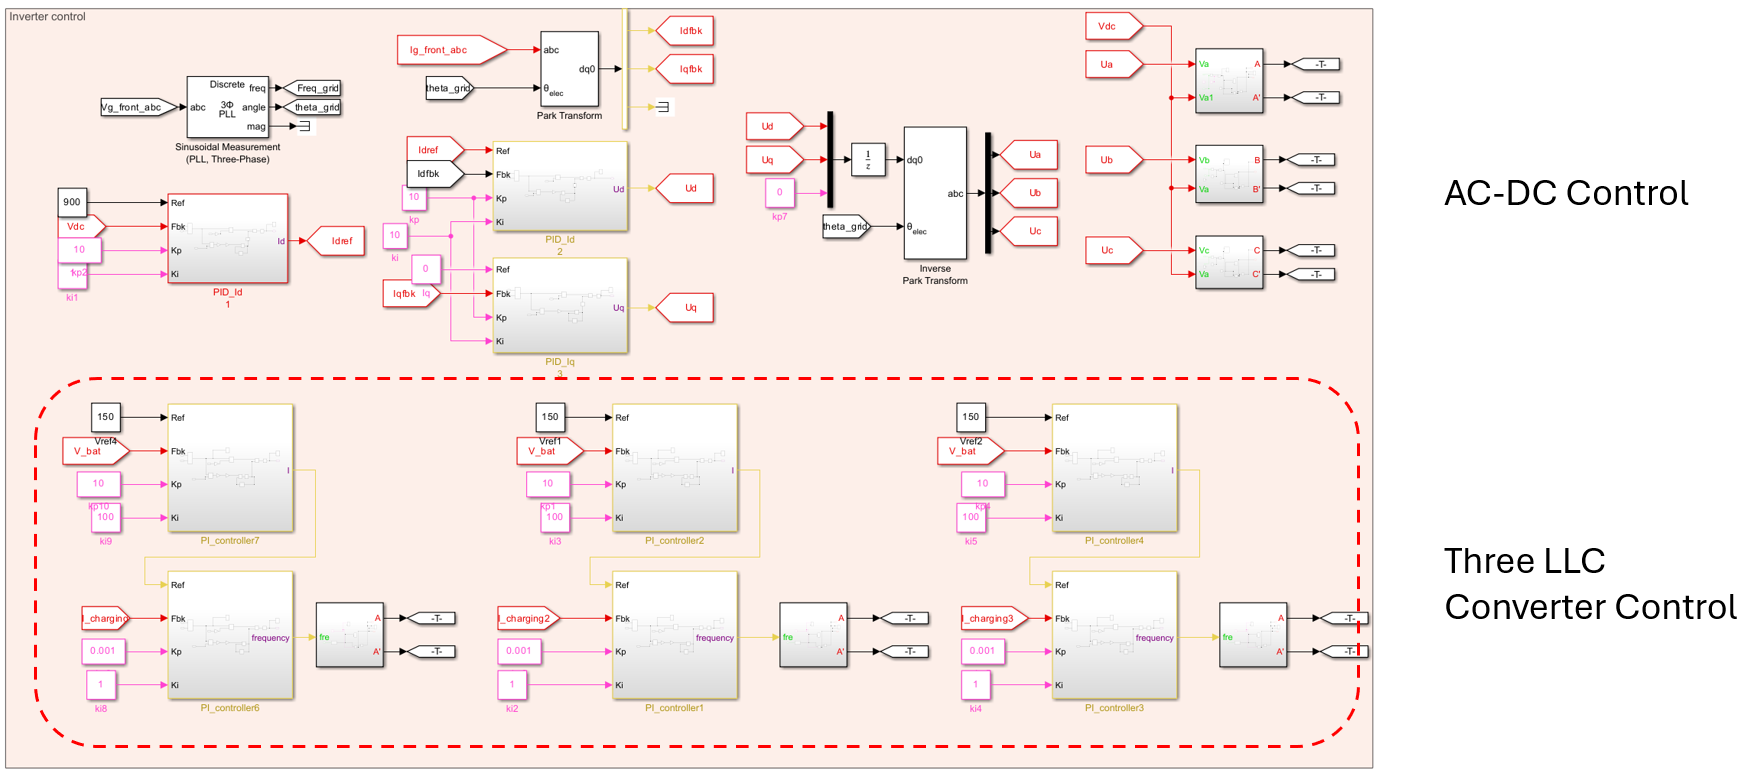

### 3.1 Charging Current and Voltage Control

The control algorithm is designed around two charging stages: constant-current charging and constant-voltage charging.

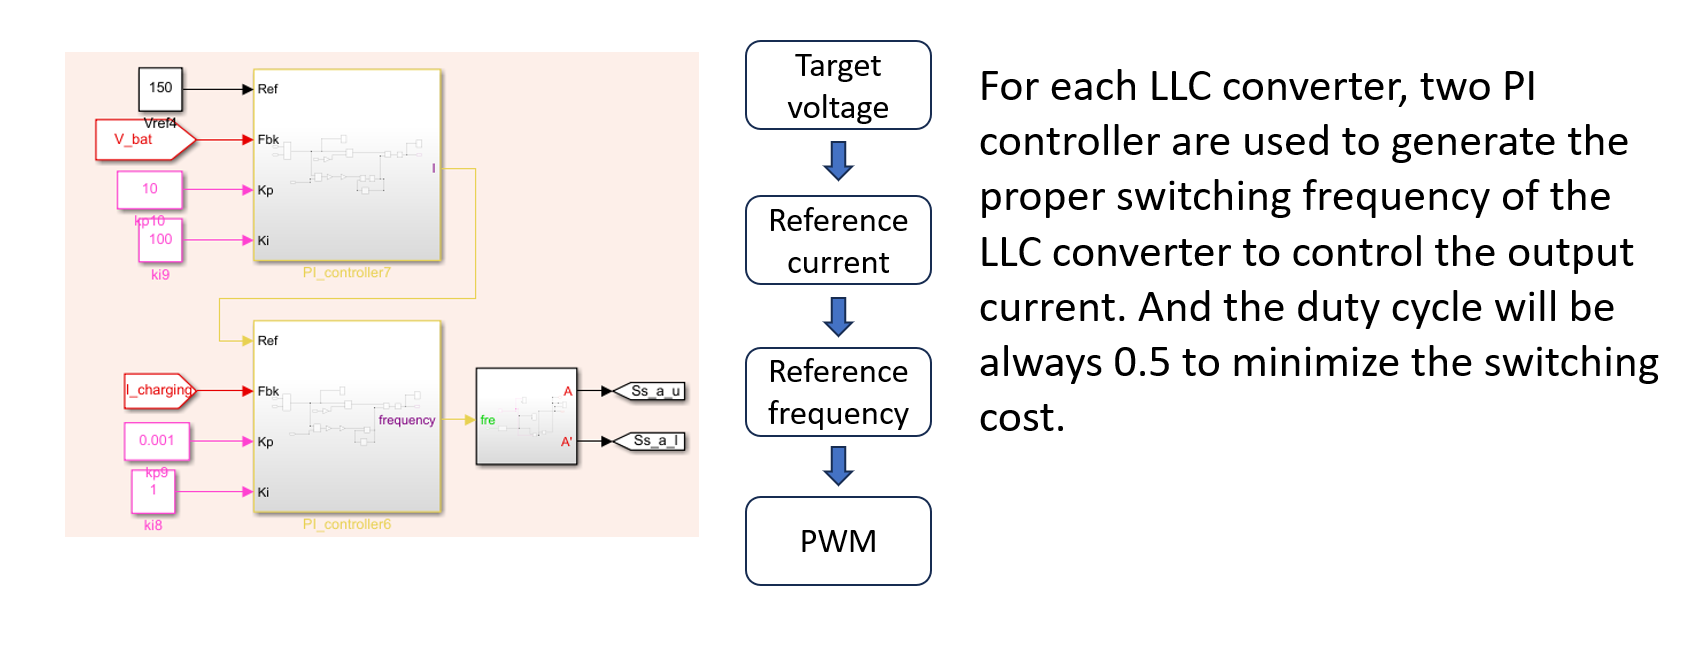

Before running, predict how battery current, battery voltage, output power, and SOC should change during charging. Once the simulation is complete (this may take a few minutes), use the following plots to evaluate your prediction:

- DC output voltage and battery current

- output power

- state of charge (SOC)

- battery terminal voltage

 
runmodel_isolated()

### **3.2 Constant current charging stage configuration.**

### 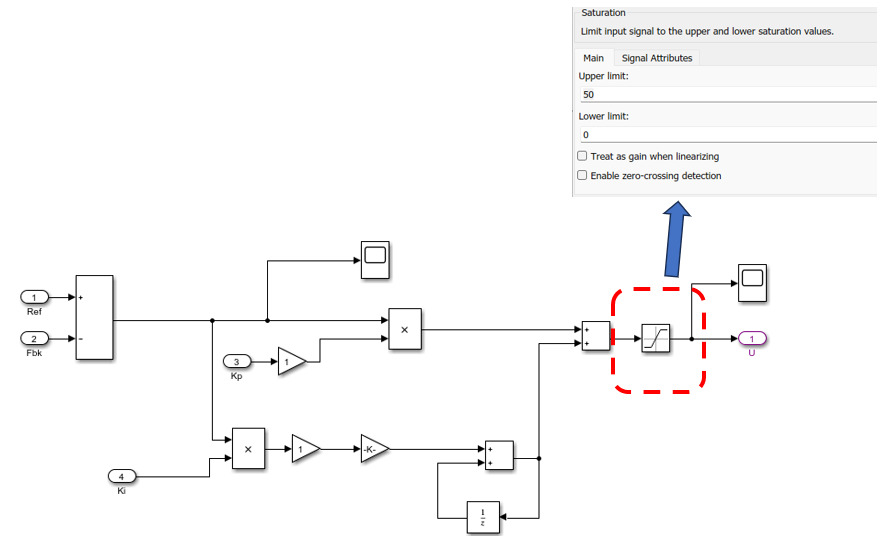

### 3.3 Inverter and DC Bus Control

The inverter control combines current control, voltage control, and duty-cycle generation.

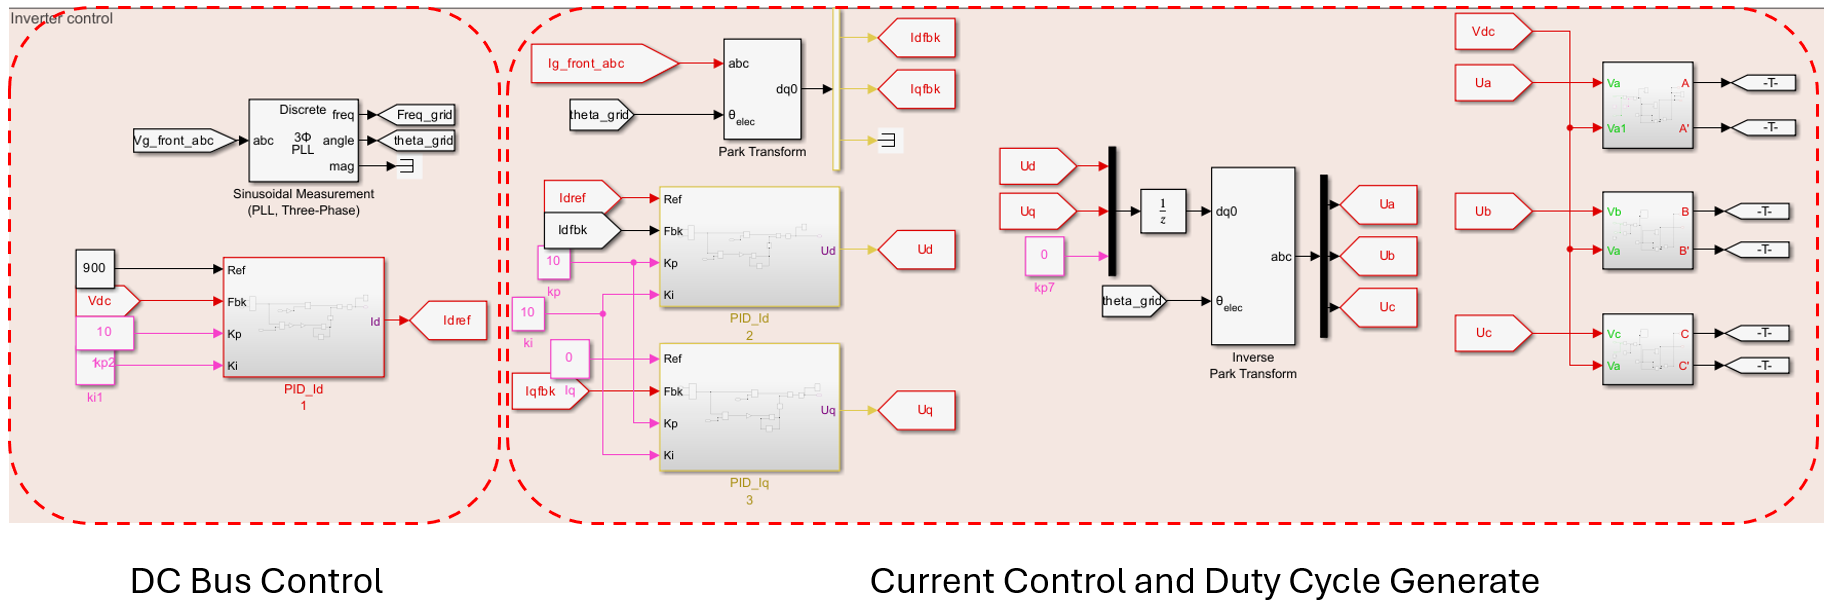

Use the drop-down menu to inspect each controller and connect it to the signals you observed in simulation.

controller("SPWM")

## 4. Analyzing the Results

Run the model if you have not done so already. After the simulation is complete (this may take a few minutes), use the scopes to evaluate the charging behavior.

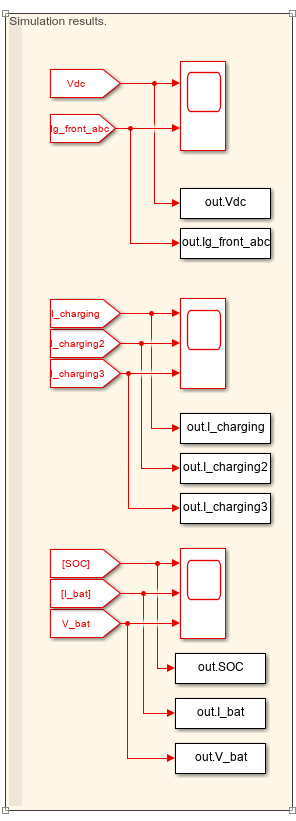

Before changing the initial SOC, predict whether the model will spend more time in constant-current charging or constant-voltage charging. Then change the initial SOC and identify where the charging mode changes.

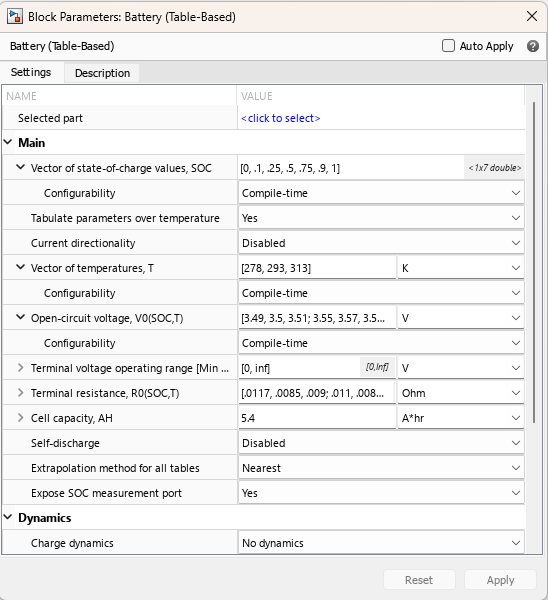

Use the menu below to compare your results with the reference simulation results.

result("No Selection")

## 5. Exercise

Exercise 1. What is the difference between an isolated charger and a non-isolated charger? Additionally, ponder why isolation matters.

exerciseSol1(...
     false, ...
   false);
 

Exercise 2. What is the final control target in the LLC resonant converter? Reflect on which signal indicates whether the target is achieved.

exerciseSol2(...
     false, ...
   false,...
  false);
 

Exercise 3. Use the simulation results to explain what may happen if the charging current is set too high.

exerciseSol3(...
     false, ...
   false,...
   false);
 

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "battery" "Grid" "Threedc"])}
end
clf;
if opt == "No Selection"
else
    if opt == "battery"
        rect = imread("Images/OffBoardCharger/battery.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Grid"
        rect = imread("Images/OffBoardCharger/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Threedc"
        rect = imread("Images/OffBoardCharger/LLC.png");
        imshow(rect, 'Interpolation', 'bilinear');
  
    end
end
end


function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "DCbus control" "Inverter control" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Inverter control"
        rect = imread("Images/OffBoardCharger/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/OffBoardCharger/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "DCbus control"
        rect = imread("Images/OffBoardCharger/dcbus.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Grid" "Battery" "Converter"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Grid"
        rect = imread("Images/OffBoardCharger/Result1.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Battery"
        rect = imread("Images/OffBoardCharger/Result2.png");
        imshow(rect,"Interpolation","bilinear");
     elseif opt == "Converter"
        rect = imread("Images/OffBoardCharger/Result3.png");
        imshow(rect,"Interpolation","bilinear");
        
    end
end
end


function exerciseSol1(A,B)
   
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end
 
    if ~any([A B])
        warning("Please select all that apply!")
    elseif A&&B
        disp("Correct!")
    else 
        disp("Incorrect. Please review the circuit section again.")
    end
end

function exerciseSol2(A,B,C)
   
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
        
    end

    if ~any([A B C])
        disp("Please select an answer!")
    elseif A+B+C > 1
        disp("Please select only one answer")
    elseif B
        disp("Correct!")
    else 
        disp("Incorrect. Please review the control section again")
    end
end
function exerciseSol3(A,B,C)
 
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        disp("Please select an answer!")
    elseif A+B+C > 1
        disp("Please select only one answer")
    elseif C
        disp("Correct!")
    else 
        disp("Incorrect.")
    end
end

function showpic1(A)
   
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/OffBoardCharger/CC.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end
function showpic2(A)
   
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/OffBoardCharger/CV.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end


function runmodel_isolated()
    warning('off', 'all'); 
    simOut = sim('Models/Isooffboard_SSC.slx'); 
    out = simOut;

    figure('Position', [100, 100, 1000, 800]);

    subplot(2,2,1); 

    plot(out.Vdc.time, out.Vdc.signals.values, 'b', out.I_bat.time, out.I_bat.signals.values, 'r', 'LineWidth', 1.2);
    title('DC Output Voltage and Battery Current');
    xlabel('Time (s)'); ylabel('Value');
    legend('V_{dc}', 'I_{bat}'); grid on;

    subplot(2,2,2); 
    plot(out.Vdc.time, out.Vdc.signals.values .* out.I_bat.signals.values, 'k', 'LineWidth', 1.2);
    title('Output Power'); xlabel('Time (s)'); ylabel('Power (W)'); grid on;

    subplot(2,2,3); 
    plot(out.SOC.time, out.SOC.signals.values, 'g', 'LineWidth', 1.2);
    title('State of Charge (SOC)'); xlabel('Time (s)'); ylabel('%'); grid on;

    subplot(2,2,4); 
    plot(out.V_bat.time, out.V_bat.signals.values, 'm', 'LineWidth', 1.2);
    title('Battery Terminal Voltage'); xlabel('Time (s)'); ylabel('V'); grid on;
end